# **demo18 of Im2mesh package**

demo18 - Create tetrahedral mesh based on 2d image

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

**To run demo18, you need to have MATLAB Partial Differential Equation Toolbox.**

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 400; height = 400;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

We add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Import image

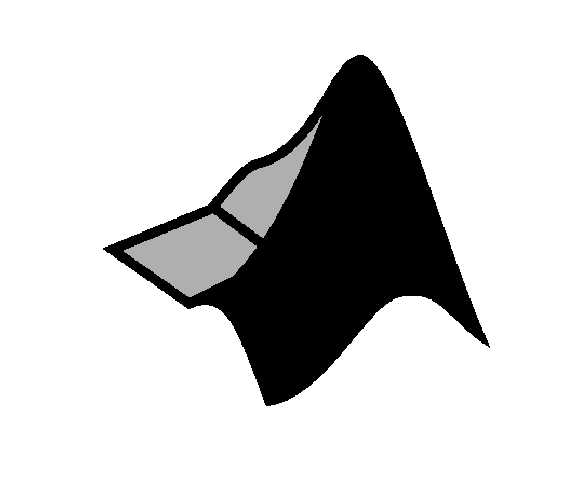

im = imread('logo.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

## Get boundries from image

We have demostrate how to do this in example3 of demo01.mlx

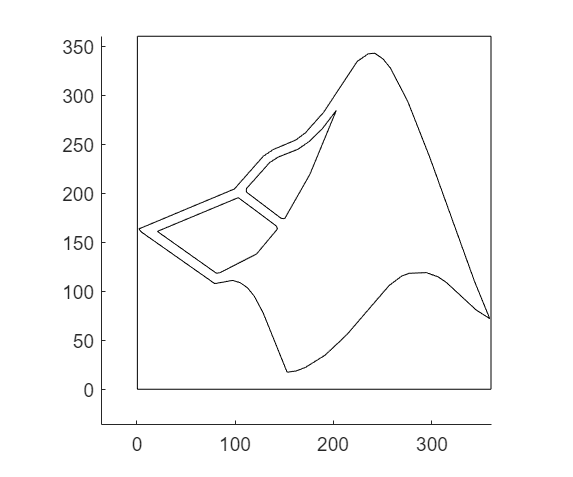

opt = [];   % reset opt
opt.tolerance = 1;
opt.tf_mesh = false;

bounds = im2mesh( im, opt );

% bounds is the simplified 2d polygonal boundaries
plotBounds( bounds );

## Create 3d pde model object

We can use function bounds2pde3d to create Matlab 3d pde model object. 

'height' is the extrusion height in the Z direction.

'scale_factor' is the scale factor for the node coordinites. We can set it as the physical dimensions of a pixel in the image.

height = 50;
scale_factor = 1;

model3d = bounds2pde3d( bounds, height, scale_factor )

model3d =   PDEModel with properties:

           PDESystemSize: 1
         IsTimeDependent: 0
                Geometry: [1×1 DiscreteGeometry]
    EquationCoefficients: []
      BoundaryConditions: []
       InitialConditions: []
                    Mesh: []
           SolverOptions: [1×1 pde.PDESolverOptions]


We can visualize the geometry.

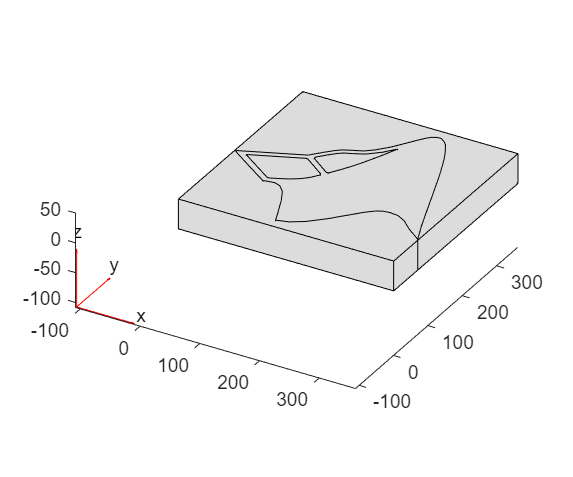

pdegplot(model3d)

Awesome!

## Generate mesh

We can use Matlab built-in function generateMesh to generate tetrahedral mesh.

generateMesh( model3d, 'Hmax',500, 'Hmin', 5, 'Hgrad', 1.2, 'GeometricOrder', 'quadratic' )

ans =   FEMesh with properties:

             Nodes: [3×22776 double]
          Elements: [10×14642 double]
    MaxElementSize: 500
    MinElementSize: 5
     MeshGradation: 1.2000
    GeometricOrder: 'quadratic'


## Plot mesh

Before plotting the mesh, we need to find elements in different phases, also known as cells or parts.

numCell = model3d.Geometry.NumCells;
elementIDsCell = cell( [1, numCell] );

for i = 1: numCell
    elementIDsCell{i} = findElements( model3d.Mesh, "region", Cell=i );
end

Now we can plot the mesh. Different phases are labelled with different colors.

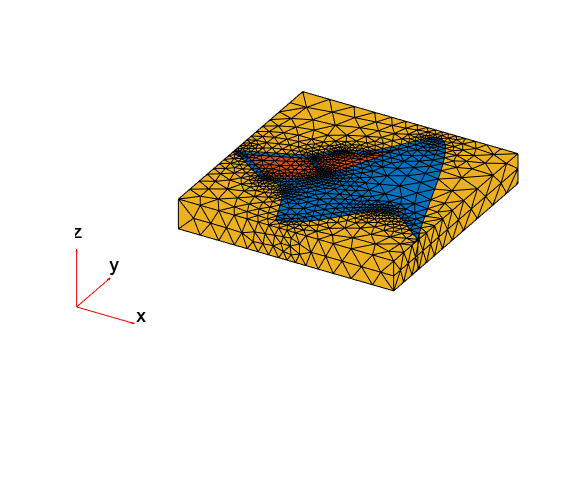

figure
colors = lines(numCell);    % colormap
for i = 1: numCell
    pdemesh( model3d.Mesh.Nodes, ...
             model3d.Mesh.Elements(:,elementIDsCell{i}), ...
             'FaceColor', colors(i,:))
    hold on
end
hold off

Awesome! We saw 3 phases in the mesh.

## Change view angle

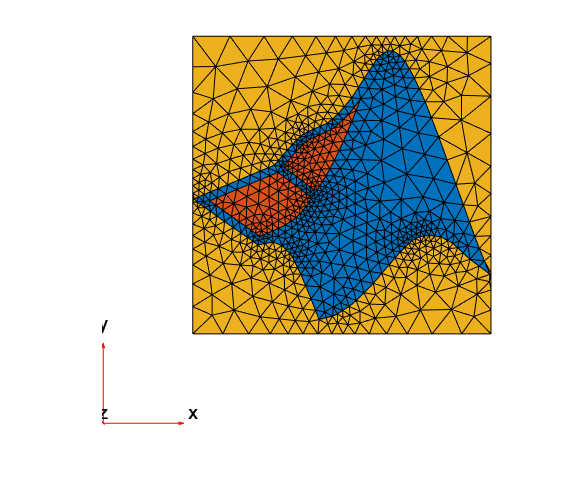

figure
colors = lines(numCell);    % colormap
for i = 1: numCell
    pdemesh(model3d.Mesh.Nodes, ...
            model3d.Mesh.Elements(:,elementIDsCell{i}), ...
            'FaceColor', colors(i,:))
    hold on
end
view([-0 90])
hold off

Please check the following link about mesh refinement.

[https://www.mathworks.com/help/pde/ug/pde.pdemodel.generatemesh.html](https://www.mathworks.com/help/pde/ug/pde.pdemodel.generatemesh.html)

## Evaluate mesh quality

We use Matlab built-in function meshQuality to check mesh qualtiy.

Q = meshQuality( model3d.Mesh );
mean(Q)

ans = 0.8509

min(Q)

ans = 0.1072

We can plot the histogram of mesh qualtiy.

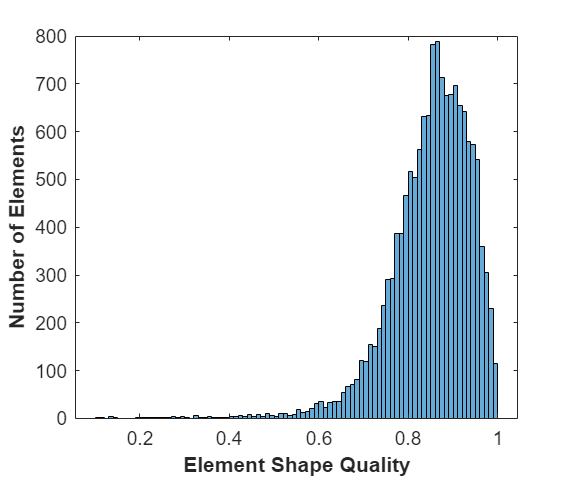

figure
histogram(Q)
xlabel( "Element Shape Quality", "fontweight", "b" )
ylabel( "Number of Elements", "fontweight", "b" )

## Extract mesh data

We can use the following code to extract mesh data from the pde model object for other purposes.

vert = model3d.Mesh.Nodes';
ele = model3d.Mesh.Elements';

numCell = model3d.Geometry.NumCells;
tnum = zeros( size(ele,1), 1 );

for i = 1: numCell
    index = findElements( model3d.Mesh, "region", Cell=i );
    tnum(index) = i;
end

We got 3 variables: vert, ele, tnum

vert: Mesh nodes. It’s a Nn-by-3 matrix, where Nn is the number of nodes in the mesh. Each row of vert contains the x, y, z coordinates for that mesh node.

ele: Mesh elements. Each row in tria contains the indices of the nodes for that mesh element.

tnum: Label of phase. Ne-by-1 array, where Ne is the number of elements.

  tnum(j,1) = k; means the j-th element belongs to the k-th phase.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo